**Wstęp**

Drugie zajęcia laboratoryjne były poświęcone zapoznaniem się z charakterystykami czasowymi oraz częstotliwościowymi często wykorzystywanych do modelowania obiektów. W pierwszej części były to proste sygnały natomiast w drugim sinusoidalne. Bardzo przydatne do zrealizowania zadania okazały się funkcje w Matlabie w szczególności nowo przeze mnie poznane bode, nyquist, longspace oraz semilogx

Przykład 1

W zaprezentowanym poniżej przeze mnie ćwiczeniu 1 należało pokazać wygląd charakterystyk czasowych kolejnych obiektów zaczynając od inercyjnego pierwszego rzędu, a kończąc na inercyjnym pierwszego rzędu z opóźnieniem. Na zajęciach zostało nam powiedziane żeby na jednym układzie rysować po dwa wykresy, dlatego też przygotowałem dwa osobne zestawy liczbowe, aby dla każdego przykładu można było uzyskać dwie osobne krzywe.

Początkowo stworzyłem odpowiedź dla obiektu inercyjnego pierwszego rzędu. Po stworzeniu dwóch zestawów liczbowych zadeklarowałem licznik i mianownik dla każdej sytuacji. Następnie funkcją tf tworzę obiekt transmitancji. Jako ostatnie zostaje już tylko narysowanie odpowiedzi skokowej i impulsowej oraz odpowiednie opisanie wykresów dla czytelności. Analogicznie postępowałem dla pozostałych obiektów.

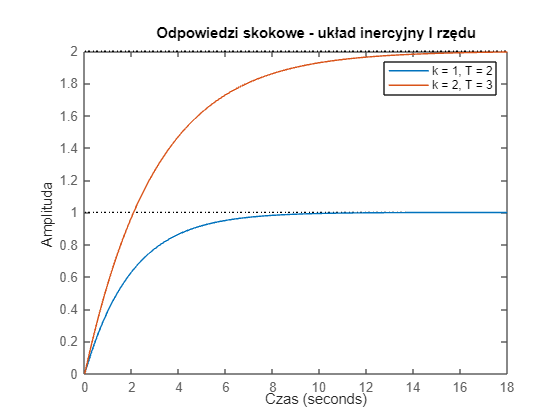

syms k1 T1 T11 T21 ksi1 Ti1 Td1 theta1 n1 % w tym miejscu zadeklarowałem wszystkie zmienne jakie będą potrzebne w przykładzie

%pierwszy zestaw liczbowy
k1 = 1;
T1 = 2;
T11 = 4;
T21 = 5;
ksi1 = 0.5; % współczynnik tłumienia zgodnie z treścią ze skryptu w jednej wersji jest mniejszy od 1 a w drugiej większy
Ti1 = 6;
Td1 = 2.5;

%drugi zestaw liczbowy
k2 = 2;
T2 = 3;
T12 = 5;
T22 = 7;
ksi2 = 4;
Ti2 = 8;
Td2 = 6;

% 1. obiekt inercyjny pierwszego rzędu
licz1_1 = [0 0 k1];
mian1_1 = [T1,1];

licz2_1 = [0 0 k2];
mian2_1 = [T2,1];

obiner1_1 = tf(licz1_1,mian1_1); % tutaj nazwałem zmienną skrótem "obiekt inercyjny 1" - pierwsza wersja oraz pod spodem druga
obiner2_1 = tf(licz2_1,mian2_1);

step(obiner1_1,obiner2_1);
title ("Odpowiedzi skokowe - układ inercyjny I rzędu"); % w tym miejscu opisałem wykres
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2', 'k = 2, T = 3');

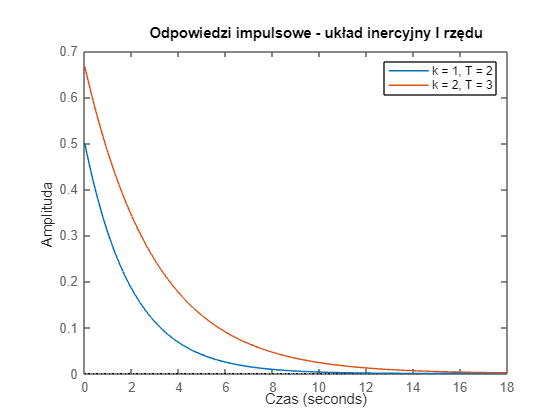

impulse(obiner1_1,obiner2_1);
title ("Odpowiedzi impulsowe - układ inercyjny I rzędu")
xlabel('Czas')
ylabel('Amplituda')
legend('k = 1, T = 2', 'k = 2, T = 3')

Na powyższych wykresach widać że współczynnik k wpływa na poziom w którym ustabilizuje się odpowiedź naszego modelu w odpowiedzi skokowej oraz poziom bazowej amplitudy w odpowiedzi impulsowej. Współczynnik T ma wpływ na czas, po którym badany obiekt się ustabilizuje.

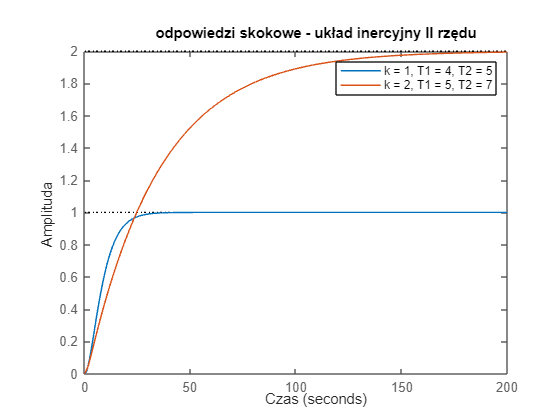

% 2.Obiekt inercyjny drugiego rzędu

licz1_2 = [0,0,k1];
mian1_2 = [T11*T21 ,T11+T21 ,1];

licz2_2 = [0,0,k2];
mian2_2 = [T12*T22 ,T12*T22 ,1];

obiner1_2 = tf(licz1_2,mian1_2);
obiner2_2 = tf(licz2_2, mian2_2);

step(obiner1_2, obiner2_2);
title("odpowiedzi skokowe - układ inercyjny II rzędu");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T1 = 4, T2 = 5', 'k = 2, T1 = 5, T2 = 7');

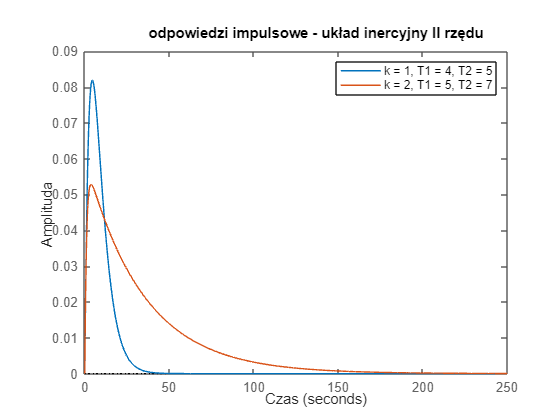

impulse(obiner1_2, obiner2_2);
title("odpowiedzi impulsowe - układ inercyjny II rzędu");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T1 = 4, T2 = 5', 'k = 2, T1 = 5, T2 = 7');

gdy połączymy szeregowo dwa obiekty inercyjne to uzyskujemy obiekt II rzędu. Stąd potrzebne było zdefiniowanie przeze mnie dwóch stałych czasowych. Wykresy różnią się odpowiedzią impulsową gdzie widoczny jest długi czas stabilizacji oraz szybkie narastanie początkowe do tzw. "piku".

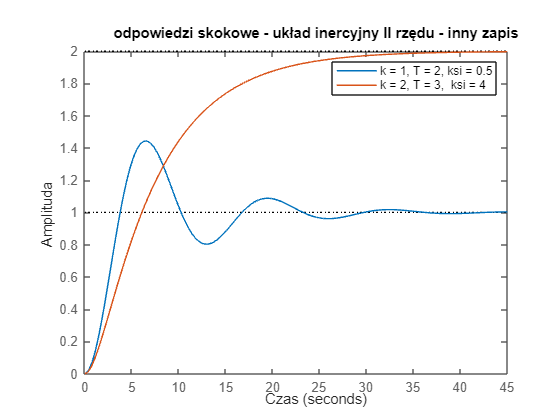

%obiekt inercyjny drugiego rzędu, ale zapisany w innej postaci

licz1_3 = [0,0,k1];
mian1_3 = [T1 * T1 ,2 * ksi1 ,1];

licz2_3 = [0,0,k2];
mian2_3 = [T2*T2 ,2 * ksi2 ,1];

obiner1_3 = tf(licz1_3, mian1_3);
obiner2_3 = tf(licz2_3, mian2_3);

step(obiner1_3, obiner2_3);
title("odpowiedzi skokowe - układ inercyjny II rzędu - inny zapis");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, ksi = 0.5', 'k = 2, T = 3,  ksi = 4');

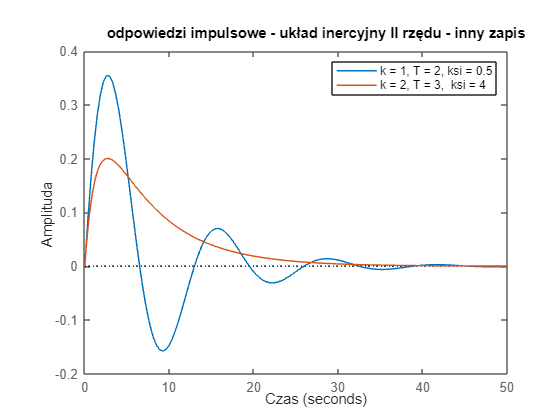


impulse(obiner1_3, obiner2_3);
title("odpowiedzi impulsowe - układ inercyjny II rzędu - inny zapis");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, ksi = 0.5', 'k = 2, T = 3,  ksi = 4');

Na powyższych wykresach doskonale widać jak się zachowuje na sygnał obiekt inercyjny II rzędu z wyższym niż 1 współczynnikiem ksi w stosunku do obiektu gdzie ten współczynnik jest mniejszy. Wykres ma znacznie mniejsze wachania amplitudy gdy ksi < 1 oraz spokojniejszy sygnał gdy wspóczynnik jest większy od 1. 

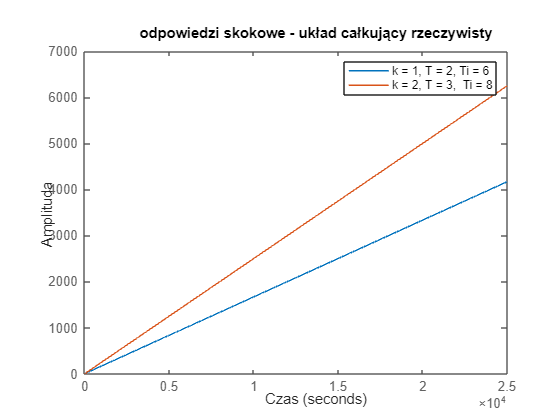

%obiekt całkujący rzeczywisty

licz1_4 = [0,0,k1];
mian1_4 = [T1 * Ti1 , Ti1 , 0];

licz2_4 = [0,0,k2];
mian2_4 = [T2*Ti2 , Ti2 ,0];

calrzecz1_4 = tf(licz1_4, mian1_4);
calrzecz2_4 = tf(licz2_4, mian2_4);

step(calrzecz1_4, calrzecz2_4);
title("odpowiedzi skokowe - układ całkujący rzeczywisty");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, Ti = 6', 'k = 2, T = 3,  Ti = 8');

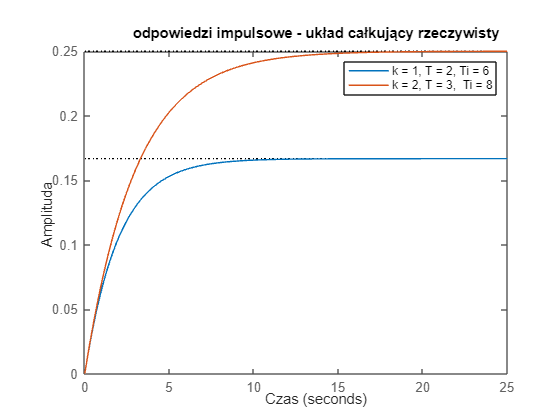

impulse(calrzecz1_4, calrzecz2_4);
title("odpowiedzi impulsowe - układ całkujący rzeczywisty");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, Ti = 6', 'k = 2, T = 3,  Ti = 8');

Obiekt różniczkujący cechuje się znacznie większą odpornością na wszelkie wachania amplitudy. Odpowiedź skokowa jest liniowa natomiast impulsowa narastająca do osiągnięcia stabilizacji

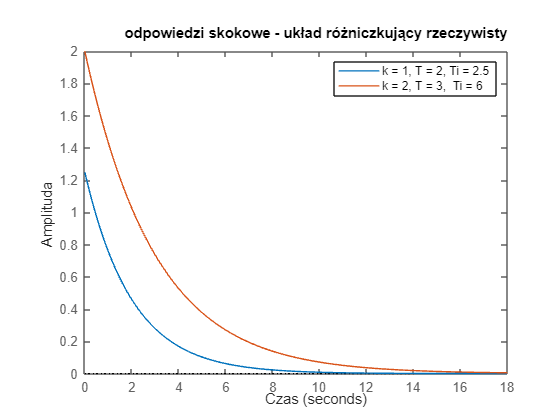

%obiekt różniczkujący rzeczywisty

licz1_5 = [Td1,0];
mian1_5 = [T1,1];

licz2_5 = [Td2,0];
mian2_5 = [T2,1];

rozrzecz1_5 = tf(licz1_5, mian1_5);
rozrzecz2_5 = tf(licz2_5, mian2_5);

step(rozrzecz1_5,rozrzecz2_5);
title("odpowiedzi skokowe - układ różniczkujący rzeczywisty");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, Ti = 2.5', 'k = 2, T = 3,  Ti = 6');

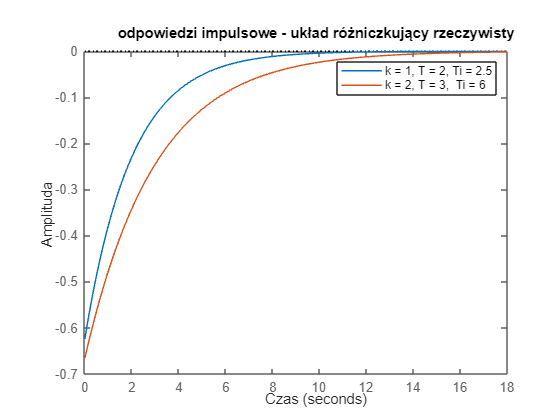

impulse(rozrzecz1_5,rozrzecz2_5);
title("odpowiedzi impulsowe - układ różniczkujący rzeczywisty");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, Ti = 2.5', 'k = 2, T = 3,  Ti = 6');

widać szybko opadającą amplitudę dla sygnału skokowego oraz szybko idącą do zera amplitudę w charakterystyce impulsowej.

Do uzyskania odpowiedzi obiektu inercyjnego pierwszego rzędu z opóźnieniem posłużyłem się przykładem 4 ze skryptu z konspektu 1. Trudność polega na niewygodzie odczytywania z formy eksponencjalnej transmitancji. Z tego powodu zamieniamy ją aproksymacją Pade'a na bardziej sprzyjający oku ułamek wielomianowy. W Matlabie wykorzystałem funkcję pade która wylicza licznik i mianownik transmitancji członu opóźniającego. Trzeba to połączyć z transmitancją obiektu inercyjnego pierwszego rzędu bez opóźnienia funkcją series.

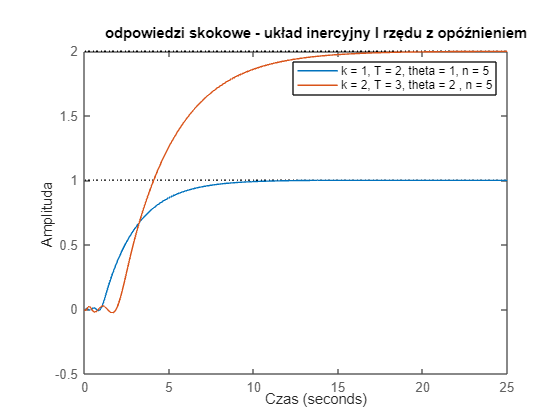

n = 5;
theta1 = 1;
[licz_cz_opoz1 , mian_cz_opoz1] = pade(theta1,n);
theta2 = 2;
[licz_cz_opoz2 , mian_cz_opoz2] = pade(theta2,n);

licz1_6 = [0,k1];
mian1_6 = [T1,1];

licz2_6 = [0,k2];
mian2_6 = [T2,1];

%dla pierwszego układu
[licznik1, mianownik1] = series(licz_cz_opoz1, mian_cz_opoz1, licz1_6, mian1_6);
obiner_zopoz1 = tf(licznik1,mianownik1);

%dla drugiego układu
[licznik2, mianownik2] = series(licz_cz_opoz2, mian_cz_opoz2, licz2_6, mian2_6);
obiner_zopoz2 = tf(licznik2,mianownik2);

step(obiner_zopoz1, obiner_zopoz2);
title("odpowiedzi skokowe - układ inercyjny I rzędu z opóźnieniem");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, theta = 1, n = 5', 'k = 2, T = 3, theta = 2 , n = 5');

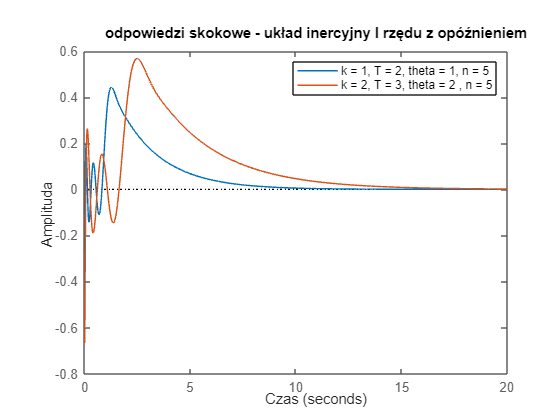


impulse(obiner_zopoz1, obiner_zopoz2);
title("odpowiedzi skokowe - układ inercyjny I rzędu z opóźnieniem");
xlabel('Czas');
ylabel('Amplituda');
legend('k = 1, T = 2, theta = 1, n = 5', 'k = 2, T = 3, theta = 2 , n = 5');

Odpowiedź zarówno impulsowa jak i skokowa cechują się początkowowymi oscylacjami. W odpowiedzi impulsowej są one duże. Jest to spowodowane opóźnieniem, poza tym wykres jest podobny do odpowiedzi obiektu inercyjnego pierwszego rzędu.

**Część II**

W tej części miałem za zadanie zapisać odpowiedzi obiektów na wymuszenia sinusoidalne. Obiekty się nie zmieniły jednak zmieniły się rodzaje wykresów. Na sygnał sinusoidalny odpowiedź będzie również sinusoidalna. Do opisu charakterystyk częstotliwościowych pomocne były dla mnie funkcje Nyquista oraz Bode'a. Prowadzący podpowiedział nam, że wykres Nyquista bardziej odpowiada automatykom. Pokazuje on dobrze zmianę ilorazu amplitud wejściowej i wyjściowej. Można go wyliczyć jako długość wektora, którego zaczepiamy w początku układu współrzędnych. Z wykresu wynika również jakie jest przesunięcie fazowe wejścia i wyjścia układu - pokazuje to kąt między wektorem a dodatnią półosią części rzeczywistych. Wykres Bode'a przedstawia amplitudę i fazę jako funkcje logarytmiczne częstotliwości co ułatwia jej interpretację w różnych zakresach częstotliwości.  Pierwszy wykres pokazuje stosunek amplitud w decybelach od pulsacji, a drugi zależność przesunięcia fazowego od pulsacji. Jest on bardziej wygodny dla projektantów czy analityków. 

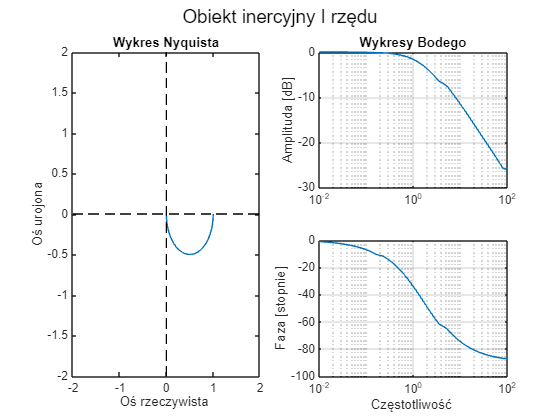

% do wykonania poniższych przykładów wykorzystałem liczniki i mianowniki z
% części pierwszej
%obiekt intercyjny 1 rzędu 
[A,F] = bode(licz1_1, mian1_1);
A_db = 20 * log10(A);
omega = logspace(-2,2,length(A));
[Re,Im] = nyquist(licz1_1, mian1_1);

subplot(2,2,[1,3]);
plot(Re(:),Im(:));

% Uzyskanie granic wykresu
xLimits = xlim; % Odczytanie granic osi X
yLimits = ylim; % Odczytanie granic osi Y

% Dodanie osi X oraz Y dla czytelności
line([-2, 2], [0, 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0, 0], [-2, 2], 'Color', 'k', 'LineStyle', '--'); % Oś Y

axis([-2, 2, -2, 2])
title("Wykres Nyquista")
xlabel("Oś rzeczywista ")
ylabel("Oś urojona")
grid off


subplot(2, 2, 2);
semilogx(omega, A_db);
title("Wykresy Bodego")
ylabel("Amplituda [dB]")
grid on

subplot(2, 2, 4)
semilogx(omega, F)
ylabel("Faza [stopnie]")
xlabel("Częstotliwość ")

grid on

sgtitle("Obiekt inercyjny I rzędu")

Do wykonania wykresów dla pierwszego przypadku użyłem funkcji bode służącej do wykreślania charakterystyk logarytmicznych. Następnie funkcją longspace tworzę wektor funkcji odciętych. Funkcją semilogx rysuję charakterystyki w skali logarytmicznej. Dla charakterystyki nyquista użyłem funckji nyquist, a następnie funkcją plot rysuję wykres o osiach rzeczywistej oraz urojonej. Wszystkie wykresy są narysowane wewnątrz jednej figure gdzie plansza jest podzielona funkcją subplot. 

Obiekt I rzędu jest filtrem dolnoprzepustowym czyli tłumi sygnały o wyższych częstotliwościach. Przesuniecie fazowe rośnie wraz ze wzrostem częstotliwości sygnału.

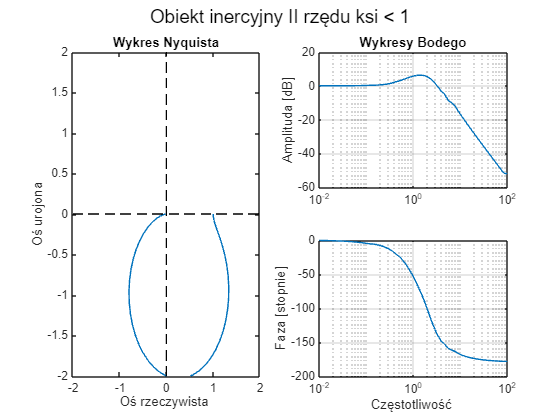


figure;
%obiekt inercyjny II rzędu ksi <  1
[A,F] = bode(licz1_3, mian1_3);
A_db = 20 * log10(A);
omega = logspace(-2,2,length(A));
[Re,Im] = nyquist(licz1_3, mian1_3);

subplot(2,2,[1,3]);
plot(Re(:),Im(:));

% Dodanie osi X oraz Y dla czytelności
line([-2, 2], [0, 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0, 0], [-2, 2], 'Color', 'k', 'LineStyle', '--'); % Oś Y

axis([-2, 2, -2, 2])
title("Wykres Nyquista")
xlabel("Oś rzeczywista ")
ylabel("Oś urojona")
grid off


subplot(2, 2, 2);
semilogx(omega, A_db);
title("Wykresy Bodego")
ylabel("Amplituda [dB]")
grid on

subplot(2, 2, 4)
semilogx(omega, F)
ylabel("Faza [stopnie]")
xlabel("Częstotliwość ")

grid on

sgtitle("Obiekt inercyjny II rzędu ksi < 1")

Wykres znacznie odbiega od tego dla obiektu inercyjnego. Wpływ na to ma współczynnik tłumienia. Wykres również przypomina delikatnie spiralę - jego przesunięcie fazowe zmienia się w czasie szybiej dla niższych częstotliwości

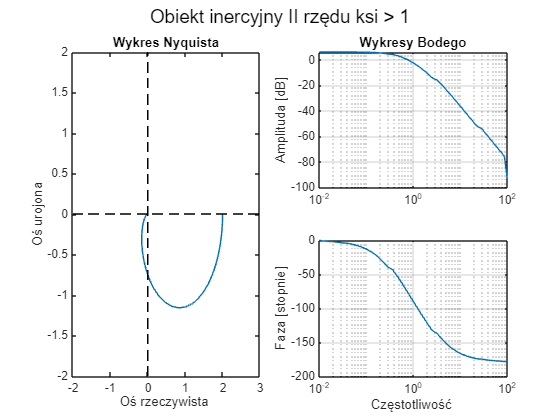

figure;
%obiekt inercyjny II rzędu ksi >  1
[A,F] = bode(licz2_3, mian2_3);
A_db = 20 * log10(A);
omega = logspace(-2,2,length(A));
[Re,Im] = nyquist(licz2_3, mian2_3);

subplot(2,2,[1,3]);
plot(Re(:),Im(:));

% Dodanie osi X oraz Y dla czytelności
line([-2, 3], [0, 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0, 0], [-2, 2], 'Color', 'k', 'LineStyle', '--'); % Oś Y

axis([-2, 3, -2, 2])
title("Wykres Nyquista")
xlabel("Oś rzeczywista ")
ylabel("Oś urojona")
grid off


subplot(2, 2, 2);
semilogx(omega, A_db);
title("Wykresy Bodego")
ylabel("Amplituda [dB]")
grid on

subplot(2, 2, 4)
semilogx(omega, F)
ylabel("Faza [stopnie]")
xlabel("Częstotliwość ")

grid on

sgtitle("Obiekt inercyjny II rzędu ksi > 1")

Wykres zwiększył się wraz ze wzrostem czynnika tłumienia - im czynnik jest większy tym wykres zbliża się wyglądowo do wykresu obiektu inercyjnego pierwszego rzędu. Na wykresie Bode'a widać przesunięcia najmocniejszego tłumienia układu.

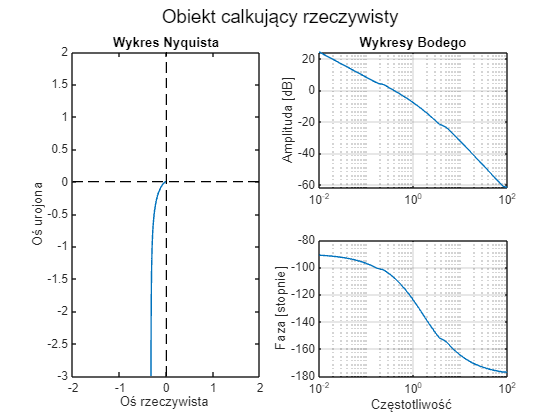


figure;

%obiekt całkujący rzeczywisty
[A,F] = bode(licz1_4, mian1_4);
A_db = 20 * log10(A);
omega = logspace(-2,2,length(A));
[Re,Im] = nyquist(licz1_4, mian1_4);

subplot(2,2,[1,3]);
plot(Re(:),Im(:));

% Dodanie osi X oraz Y dla czytelności
line([-2, 2], [0, 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0, 0], [-3, 2], 'Color', 'k', 'LineStyle', '--'); % Oś Y

axis([-2, 2, -3, 2])
title("Wykres Nyquista")
xlabel("Oś rzeczywista ")
ylabel("Oś urojona")
grid off


subplot(2, 2, 2);
semilogx(omega, A_db);
title("Wykresy Bodego")
ylabel("Amplituda [dB]")
grid on

subplot(2, 2, 4)
semilogx(omega, F)
ylabel("Faza [stopnie]")
xlabel("Częstotliwość ")

grid on

sgtitle("Obiekt calkujący rzeczywisty")

Obiekt wyraźnie wzmacnia sygnał dla niskich częstotliwości natomiast tłumi sygnał o wysokich częstotliwościach.

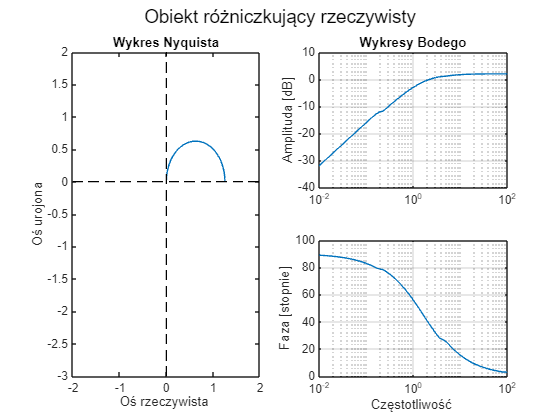

figure;
%obiekt różniczkujący rzeczywisty
[A,F] = bode(licz1_5, mian1_5);
A_db = 20 * log10(A);
omega = logspace(-2,2,length(A));
[Re,Im] = nyquist(licz1_5, mian1_5);

subplot(2,2,[1,3]);
plot(Re(:),Im(:));

% Dodanie osi X oraz Y dla czytelności
line([-2, 2], [0, 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0, 0], [-3, 2], 'Color', 'k', 'LineStyle', '--'); % Oś Y

axis([-2, 2, -3, 2])
title("Wykres Nyquista")
xlabel("Oś rzeczywista ")
ylabel("Oś urojona")
grid off


subplot(2, 2, 2);
semilogx(omega, A_db);
title("Wykresy Bodego")
ylabel("Amplituda [dB]")
grid on

subplot(2, 2, 4)
semilogx(omega, F)
ylabel("Faza [stopnie]")
xlabel("Częstotliwość ")

grid on

sgtitle("Obiekt różniczkujący rzeczywisty")

Wykres przeciwnie skręca co do pozostałych. Jest to odbicie przez oś rzeczywistą wykresu obiektu inercyjnego I rzędu. Przesunięcie fazowe jest największa dla niskich częstotliwości. Obiekt działa jak filtr górnoprzepustowy gdyż niweluje sygnały o niskiej częstotliwości, a przenosi sygnały szybko zmienne.

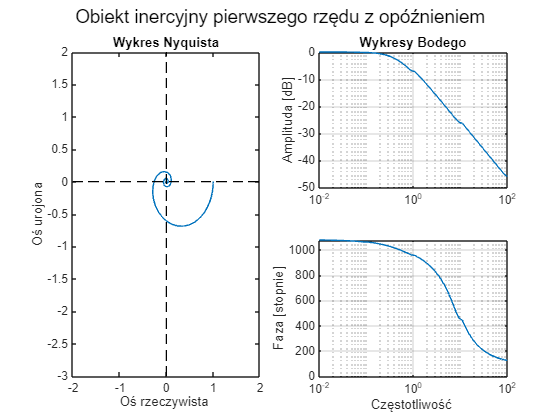

figure;

%obiekt inercyjny pierwszego rzędu z opóźnieniem
[A,F] = bode(licznik1, mianownik1);
A_db = 20 * log10(A);
omega = logspace(-2,2,length(A));
[Re,Im] = nyquist(licznik1, mianownik1);

subplot(2,2,[1,3]);
plot(Re(:),Im(:));

% Dodanie osi X oraz Y dla czytelności
line([-2, 2], [0, 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0, 0], [-3, 2], 'Color', 'k', 'LineStyle', '--'); % Oś Y

axis([-2, 2, -3, 2])
title("Wykres Nyquista")
xlabel("Oś rzeczywista ")
ylabel("Oś urojona")
grid off


subplot(2, 2, 2);
semilogx(omega, A_db);
title("Wykresy Bodego")
ylabel("Amplituda [dB]")
grid on

subplot(2, 2, 4)
semilogx(omega, F)
ylabel("Faza [stopnie]")
xlabel("Częstotliwość ")

grid on

sgtitle("Obiekt inercyjny pierwszego rzędu z opóźnieniem")

Na wykresie widać silne przesunięcie fazowe dla niskich częstotliwości, które się zmniejsza wraz z jej wzrostem. Przez to sygnały o niskiej częstotliwości są tłumione, a te o wyższej odbierane. Dodatkowo w porównaniu do innych wykresów na tym widoczna jest "spirala" silnie związana z efektem członu opóźniającego